# `RadarScope`** Examples**

## **Import the blip data.**

blipFile = fullfile( chartsDocRoot(), "data", "Blips.csv" );
blipData = readtable( blipFile, "TextType", "string" );
disp( blipData )

      Tag       Theta      Rho  
    _______    _______    ______

    "VQ228"     2.6651    25.806
    "UP436"      3.191    40.872
    "QF311"    0.53731     59.49
    "JH923"     1.6492    26.221
    "VM430"     5.0329    60.284
    "NF185"     0.1836    71.122
    "JV904"     5.8362    22.175
    "YF979"     4.5888    11.742
    "WF439"       3.07    29.668
    "OE112"      3.635    31.878



## Create a figure for the radar scope.

f = exampleFigure( "Name", "RadarScope Examples" );

## Create the radar scope.

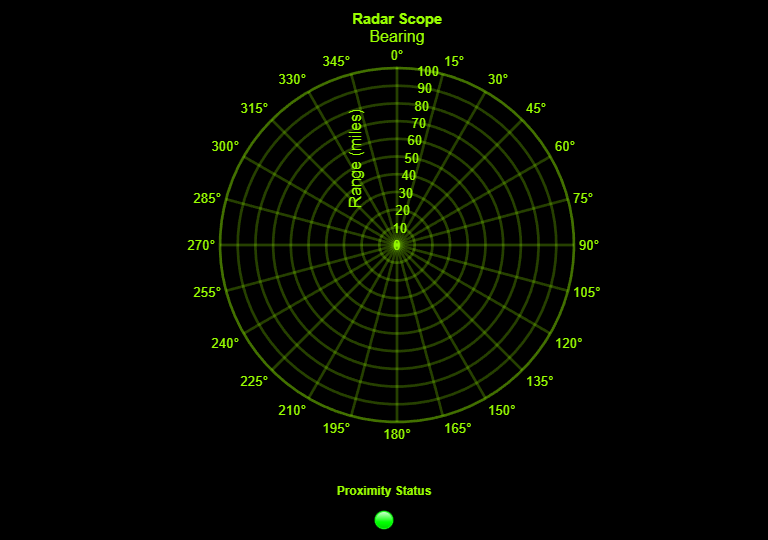

RS = RadarScope( "Parent", f );

## Create an array of blips and add them to the scope.

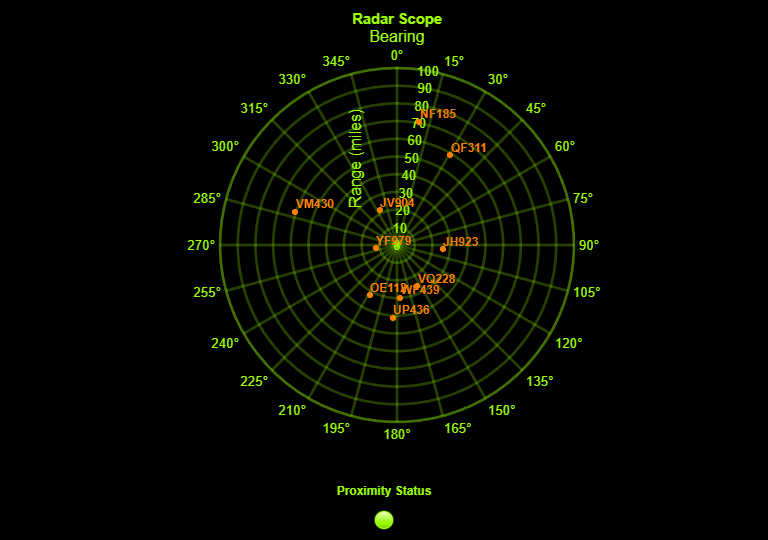

for k = 1 : height( blipData )
    B(k, 1) = Blip( "Position", [blipData.Theta(k), blipData.Rho(k)], ...
        "String", blipData.Tag(k) );
    RS.addBlip( B(k, 1) )
end % for

## Move one of the blips.

theta = linspace( 0, 2 * pi ).';
for k = 1 : numel( theta )
    B(1).Position(1) = theta(k);
    pause( 0.1 )
end % for